[filename,pathname]=uigetfile('*.*','Select the ECG signal');
filewithpath=strcat(pathname,filename);
Fs=input('Input sampling rate (360Hz for MIT_BH and 500Hz for ECG_ID:'); %taking sampling frequency 

%Loading data from the dataset
ecg=load(filename);
ecgsig=(ecg.val)./200; %Normalizing data
t=1:length(ecgsig); %number of samples 
tx=t./Fs; %time vector 

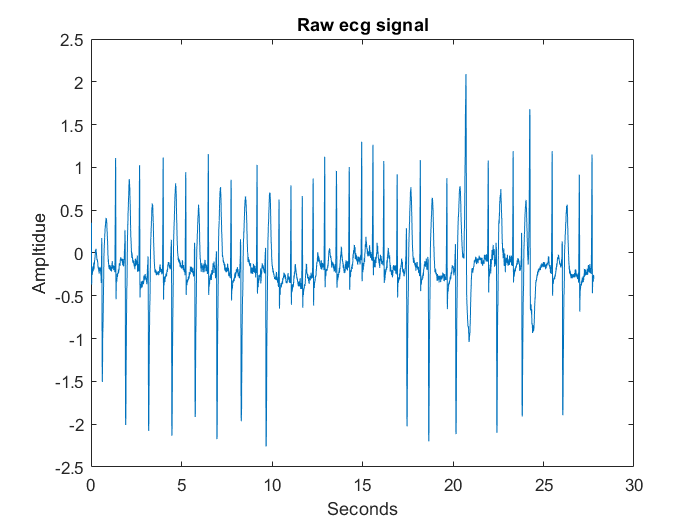

%Plotting the raw signal 
figure;
plot(tx,ecg.val);
xlabel('Seconds');
ylabel('Ampltidue');
title('Raw ecg signal');

%Filtration using butterworth filter 
f_low=5;
f_high=15;
[b,a]=butter(2,[f_low,f_high]/(Fs/2));
filtered_ecg=filtfilt(b,a,ecg.val);

%Applying symlet4 wavelet transform 
wt=modwt(ecgsig,4,'sym4'); %performing 4 level undecimated dwt
wtrec=zeros(size(wt));
wtrec(3:4,:)=wt(3:4,:)

wtrec =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

%Applying inverse wavelet transform to obtain the signal
y=imodwt(wtrec,'sym4'); %IDWT with only d3 and d4 coefficients 
y=abs(y);
avg=mean(y);

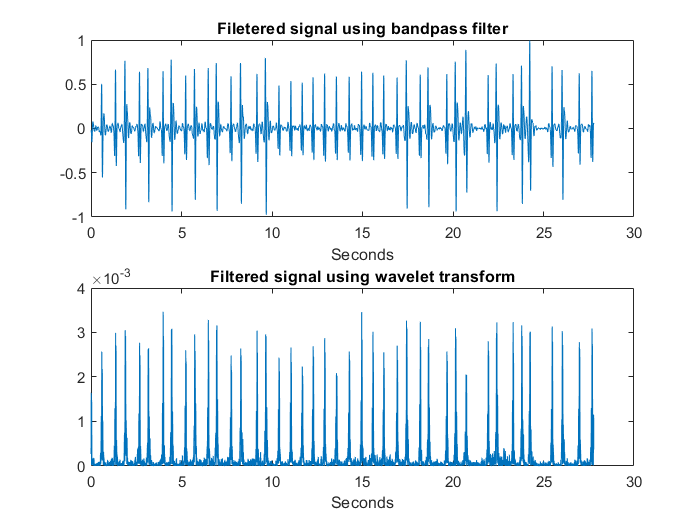

%Comparing the signal using bandpass filter and wavelet transform
figure;
subplot(2,1,1)
plot(tx,filtered_ecg);
xlabel('Seconds');
title('Filetered signal using bandpass filter');
subplot(2,1,2)
plot(tx,y);
xlabel('Seconds');
title('Filtered signal using wavelet transform');

%Finding Peaks
[Rpeaks,locs]=findpeaks(y,t,'MinPeakHeight',8*avg,'MinPeakDistance',50);
nohb=length(locs); %No of beats 
timelimit=length(ecgsig)/Fs;
hbpermin=(nohb*60)/timelimit; %calculating heartbeat
disp(strcat('Heart Rate=',num2str(hbpermin)))

Heart Rate=84.24


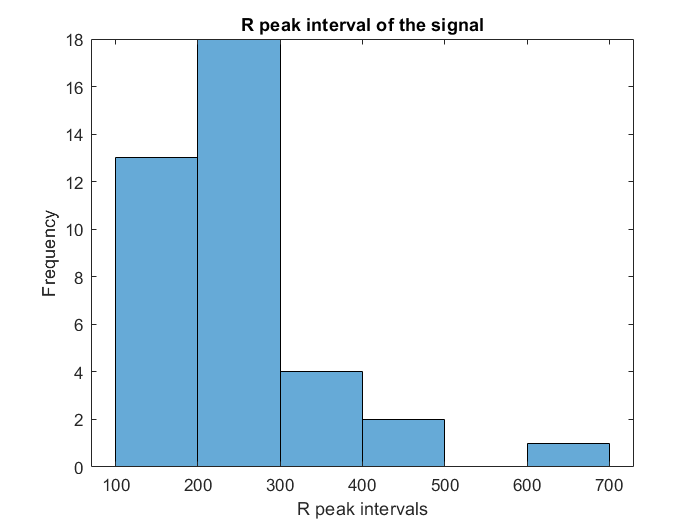

%Finding and displaying the peak intervals 
R_R_interval=diff(locs);
figure;
histogram(R_R_interval);
grid on;
xlabel("R peak intervals");
ylabel("Frequency");
title("R peak interval of the signal");
grid off;

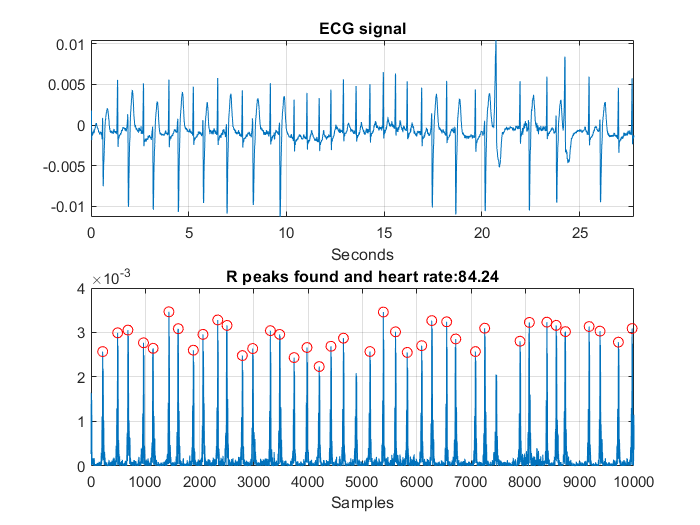

figure
subplot(2,1,1);
plot(tx,ecgsig);
xlim([0,timelimit]);
grid on;
xlabel('Seconds');
title('ECG signal');

subplot(2,1,2);
plot(t,y);
grid on;
xlim([0,length(ecgsig)]);
hold on;
plot(locs,Rpeaks,'ro')
xlabel('Samples');
title(strcat('R peaks found and heart rate:',num2str(hbpermin)))